rng (7)
n = 30;
center = [0 0];
radius = 1;
eps = 0.1;
r = eps * rand (n ,1) + radius - eps /2;
A = [center(1) + r .* cos(2*pi*(1:n)'/n) center(2) + r .* sin(2*pi*(1:n)'/ n)]

A =     0.9367    0.1991
    0.9391    0.4181
    0.8040    0.5842
    0.6841    0.7598
    0.5239    0.9074
    0.3102    0.9547
    0.1045    0.9946
   -0.1001    0.9520
   -0.3019    0.9290
   -0.5000    0.8660


b = A(:,1) .^2 + A(:, 2) .^2;
A1 = [A(:, 1).*2, A(:, 2).*2];
A1(:,3) = ones;

c = A1 \ b

c =     0.0050
   -0.0021
    1.0035



c1 = c(1);
c2 = c(2);
c3 = c(3);
radien = sqrt(c3 + c2 ^ 2 + c1 ^ 2);

radien = 1.0018

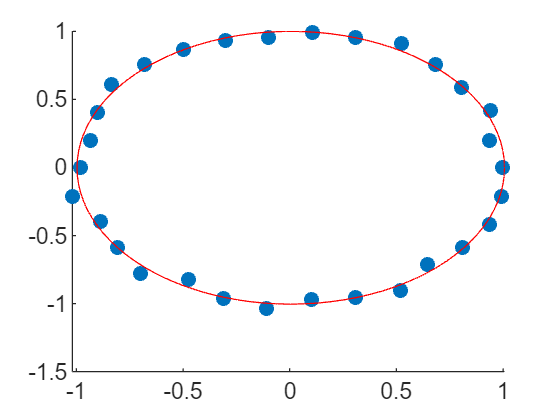

theta = 0:pi/50:2*pi;
x_circle = radien * cos(theta) + c1;
y_circle = radien * sin(theta) + c2;

scatter(A(:, 1), A(:, 2), 'o', 'filled');
hold on;
plot(x_circle, y_circle, 'r');
hold off;


x = A(:, 1);
y = A(:, 2);
summa = 0;
for j = 1:n
   summa = summa + (radien^2 - (x(j) - c1)^2 - (y(j) - c2)^2) ^ 2;
end 
MSE = 1/n * summa

MSE = 0.0033